% ejercicio2_from_wheels.m
clear; close all; clc;

%% Parámetros y tiempo
r  = 0.1;     % radio de rueda [m]
L  = 0.4;     % separación ejes [m]
dt = 1;       % paso de muestreo [s]
t  = (0:20)'; % 0,1,...,20
N  = length(t);

%% Señales de entrada (ω_R y ω_L)
omega_R = [ ...
    4.582; 4.773; 5.291; 5.960; 6.490; ...
   -1.168; -1.364; 5.960; 5.291; 4.773; ...
    4.582; 4.773; 5.291; 5.960; 6.490; ...
    6.686; 6.490; 5.960; 5.291; 4.773; 4.582 ];
omega_L = [ ...
    1.701; 2.353; 3.676; 4.856; 5.618; ...
   13.735;13.472; 4.856; 3.676; 2.353; ...
    1.701; 2.353; 3.676; 4.856; 5.618; ...
    5.881; 5.618; 4.856; 3.676; 2.353; 1.701 ];
assert(numel(omega_R)==N && numel(omega_L)==N);

%% Cinemática diferencial
v = r*(omega_R + omega_L)/2;        % [m/s]
w = r*(omega_R - omega_L)/L;        % [rad/s]

%% Integración Euler
x = zeros(N,1); 
y = zeros(N,1);
phi = zeros(N,1);
for k = 1:N-1
    phi(k+1) = phi(k) + w(k)*dt;
    x(k+1)   = x(k)   + v(k)*cos(phi(k))*dt;
    y(k+1)   = y(k)   + v(k)*sin(phi(k))*dt;
end

%% Tabla de resultados
T2 = table( ...
  t, v, w, omega_R, omega_L, x, y, rad2deg(phi), ...
  'VariableNames', ...
  {'t_s','v_m_s','omega_rad_s','omega_R','omega_L','x_m','y_m','theta_deg'});
disp(T2);

    t_s     v_m_s     omega_rad_s    omega_R    omega_L       x_m         y_m        theta_deg 
    ___    _______    ___________    _______    _______    _________    ________    ___________

     0     0.31415      0.72025       4.582      1.701             0           0              0
     1      0.3563        0.605       4.773      2.353       0.31415           0         41.267
     2     0.44835      0.40375       5.291      3.676       0.58196     0.23501         75.931
     3      0.5408        0.276        5.96      4.856       0.69095     0.66991         99.064
     4      0.6054        0.218        6.49      5.618       0.60575       1.204         114.88
     5     0.62835      -3.7257      -1.168     13.735 

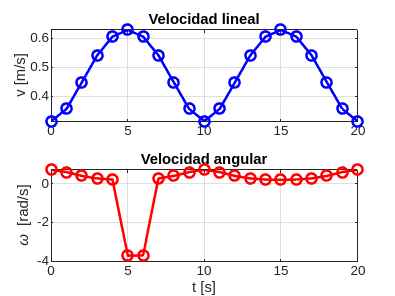


%% Gráfica v y ω
figure;
subplot(2,1,1)
plot(t, v,'b-o','LineWidth',1.5), grid on
ylabel('v [m/s]'), title('Velocidad lineal')
subplot(2,1,2)
plot(t, w,'r-o','LineWidth',1.5), grid on
xlabel('t [s]'), ylabel('\omega [rad/s]'), title('Velocidad angular')

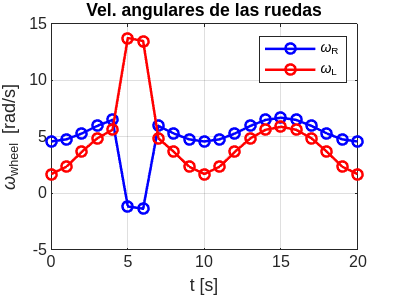


%% Gráfica de velocidades de rueda
figure;
plot(t, omega_R,'b-o', t, omega_L,'r-o','LineWidth',1.5), grid on
xlabel('t [s]'), ylabel('\omega_{wheel} [rad/s]')
legend('\omega_R','\omega_L'), title('Vel. angulares de las ruedas')

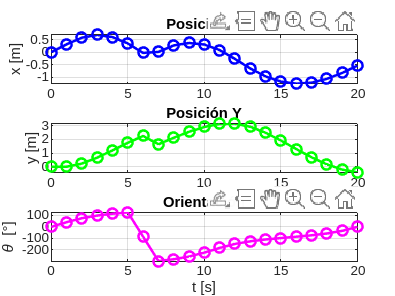


%% Gráficas de pose
figure;
subplot(3,1,1)
plot(t, x,'b-o','LineWidth',1.5), grid on, ylabel('x [m]'), title('Posición X')
subplot(3,1,2)
plot(t, y,'g-o','LineWidth',1.5), grid on, ylabel('y [m]'), title('Posición Y')
subplot(3,1,3)
plot(t, rad2deg(phi),'m-o','LineWidth',1.5), grid on, 
xlabel('t [s]'), ylabel('\theta [°]'), title('Orientación')

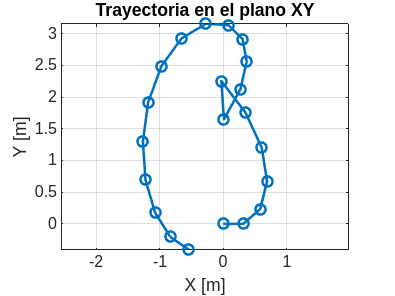


%% Trayectoria estática XY
figure;
plot(x, y,'-o','LineWidth',1.5), axis equal, grid on
xlabel('X [m]'), ylabel('Y [m]'), title('Trayectoria en el plano XY')

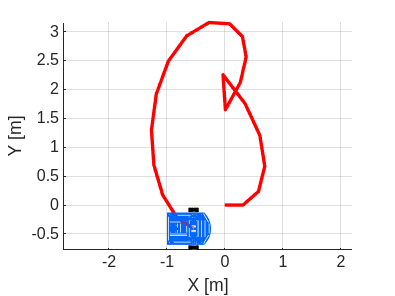


%% Animación 2D
figure; axis equal; grid on; hold on
xlabel('X [m]'), ylabel('Y [m]'), view(2)
MobileRobot_5; scale=4;
hR = MobilePlot_4(x(1), y(1), phi(1), scale);
hT = plot(x(1), y(1), 'r-','LineWidth',2);
for k = 2:N
    delete(hR); delete(hT)
    hR = MobilePlot_4(x(k), y(k), phi(k), scale);
    hT = plot(x(1:k), y(1:k), 'r-','LineWidth',2);
    pause(dt)
end